clear all;
close all;
clc
N = 6; %resolution
Vcm = 0.7; 
fs = 20000; %sampling rate

Weight=[32 16 8 4 2 1]

Weight =     32    16     8     4     2     1


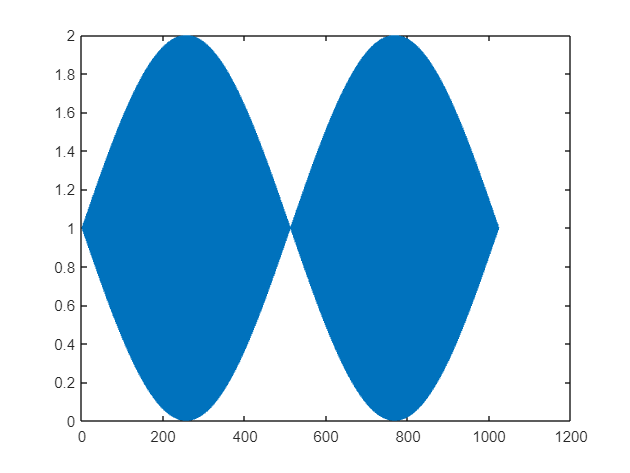

sampling_points=1024;
data=csvread('final_enob_1.98.csv',2,1);
Digital_code = zeros(sampling_points,N);
%Convert analog signal to digital code
for i= 1:sampling_points
    for j = 1:N
        if data(i,j)>Vcm
            Digital_code(i,j)=1;
        end
    end
end
Daq = zeros(sampling_points,1);
for k=1:sampling_points
    for i=1:N
        Daq(k) = Daq(k) + (2^(N-i)).*Digital_code(k,i);
    end
end

n=0:1023;
Daq_1 = sin(2*pi*n*511/1024)+1;
Daq_1 = rot90(Daq_1);
plot(Daq_1);

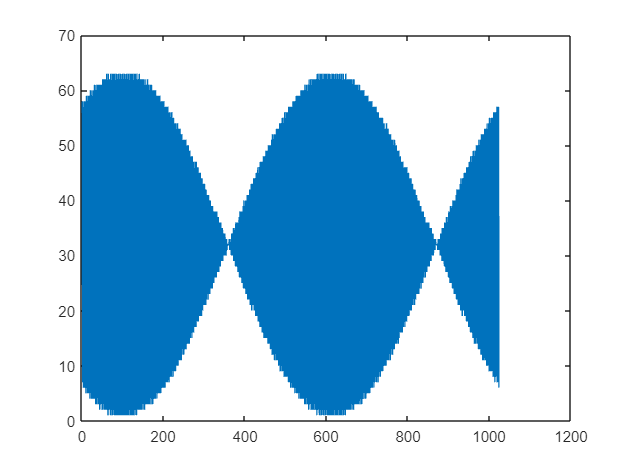

plot(Daq);

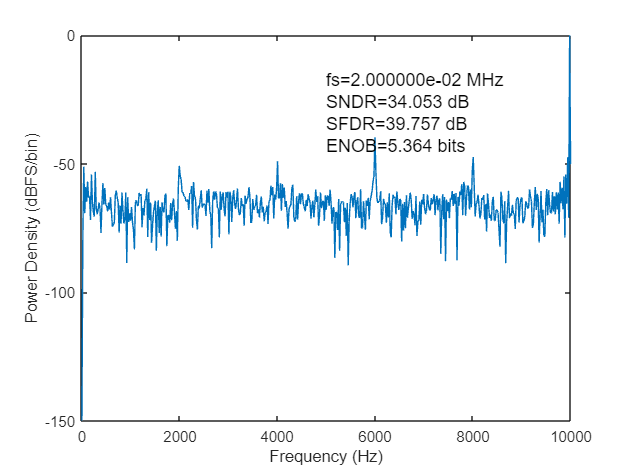

ENOB = 5.3643

SNDR = 34.0533

SFDR = 39.7566


[ENOB ,SNDR, SFDR]=FreqA(Daq,fs)